# DSZOB, cvičenie 8.

## **Zadanie:**

## **Úloha 1 Lineárna filtrácia obrazu v priestorovej doméne**

Vykonajte filtráciu obrazu v priestorovej doméne s využitím konvolúcie. Použite nasledovné filtre:

- Gaussov filter

- Sobelov filter

- Laplacov filter

Postupujte nasledovne:

1. Načítajte si ľubovolný obrázok (imread).

2. Preveďte si obrázok na grayscale (rgb2gray).

    a. Dobrovolné: Môžete robiť aj s farebným rgb obrázkom (3 kanály).

3. Vytvorte si maticu filtra pre konvolúciu (pomôcka: fspecial).

4. Vykonajte konvolúciu (conv2).

V úlohe vizualizujte pôvodný obrázok a výstupy po filtrácii.

**Posudte ci pouzite filtracne jadra pri konvolucii su LP alebo HP! Zdôvodnite !**

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Riesenie / Solution
clear;

cat = imread('Asignments\Assignment_7\cat.jpg');

cat_gray = rgb2gray(cat);

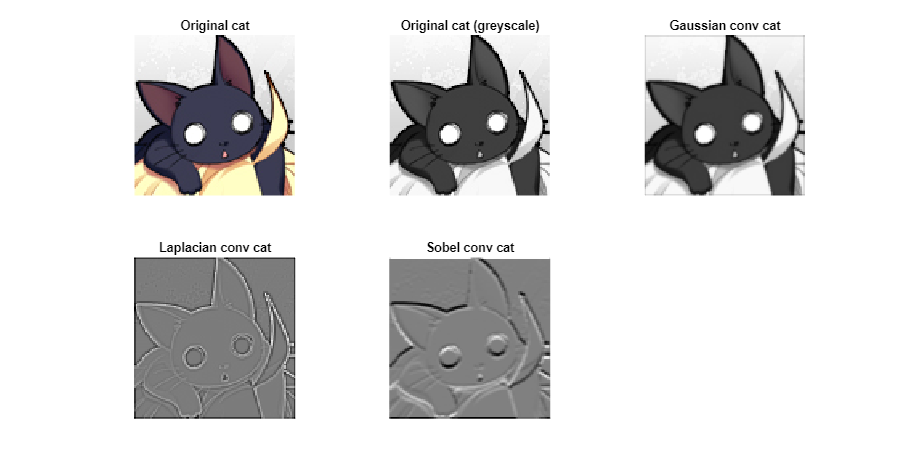

close all;

foo = figure('Position', [100, 100, 2024, 1048]);

subplot(2,3,3);
imshow(conv2(cat_gray, fspecial("gaussian", [11,11]), "same"), []);
title("Gaussian conv cat");

subplot(2,3,2);
imshow(cat_gray, []);
title("Original cat (greyscale)");

subplot(2,3,1);
imshow(cat, []);
title("Original cat");

subplot(2,3,4);
imshow(conv2(cat_gray, fspecial("laplacian", .5), "same"), []);
title("Laplacian conv cat");

subplot(2,3,5);
imshow(conv2(cat_gray, fspecial("sobel"), "same"), []);
title("Sobel conv cat");

Both Sobel  filter and Laplacian filter are high pass filters, they both highlight edges in the image by detecting sharp changes in intensity between pixels. 

Gaussian filter is low pass, it reduces noise and makes the image more "blurry"

## **Úloha 2 F**iltrácia obrazu v spektrálnej doméne

Vykonajte nasledovné filtrácie obrazu v spektrálnej doméne:

• Ideálny HP filter

• Ideálny LP filter

• Gaussov HP filter

• Gaussov LP filter

Postupujte nasledovne:

1. Načítajte si obrázok a preveďte ho na grayscale (dobrovoľné: RGB).

2. Vypočítajte Fourierovu transformáciu nad obrázkom (fft2).

3. Správne si posuňte spektrum (prehodenie kvadrantov) (fftshift).

4. Vytvorte si ideálny filter (pomôcka: definícia funkcie pre kruh s využitím polomeru a stredového bodu).

5. Vykonajte filtráciu. (násobenie)

6. Inverzne posuňte spektrum (ifftshift).

7. Vykonajte spätnú transformáciu (ifft2) a vizualizujte obrázok.

Rovnako postupujte aj pri ostatných filtroch. Pri vytvaraní Gaussovho filtra cez fspecial si správne naškálujte filter (pozn. min = 0, max = 1). Vizualizujte aj jednotlivé filtre, ktoré ste vytvorili v tejto úlohe. **Porovnajte a zhodnoďte vplyv jednotlivých filtrov na výsledné vizualizácie.**

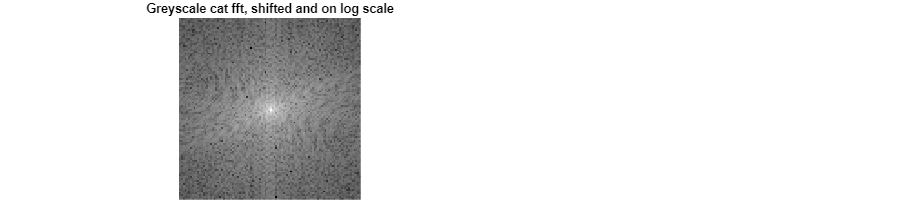

% Riesenie / Solution
close all;
foo = figure('Position', [100, 100, 2024, 500]);

shifty_cat = fftshift(fft2(cat_gray));

subplot(1,2,1);
imshow(log(abs(shifty_cat)), []);
title("Greyscale cat fft, shifted and on log scale");

%somel and laplaz 3x3 kernel

close all;

foo = figure('Position', [100, 100, 2024, 1000]);

subplot(2,3,1);
imshow(perfect_low_pass(cat_gray, 50), []);
title("Ideal Low pass");

subplot(2,3,2);
imshow(ifft2(ifftshift(perfect_low_pass(shifty_cat, 20))), []);

title("Ideal Low pass in spectral domain");

subplot(2,3,3);
imshow(ifft2(ifftshift(perfect_high_pass(shifty_cat, 20))), []);

title("Ideal High pass in spectral domain");

subplot(2,3,4);
imshow(ifft2(ifftshift(gauss_high_pass(shifty_cat, 20))), []);

title("Gauss high pass in spectral domain");

subplot(2,3,5);
imshow(ifft2(ifftshift(gauss_low_pass(shifty_cat, 20))), []);

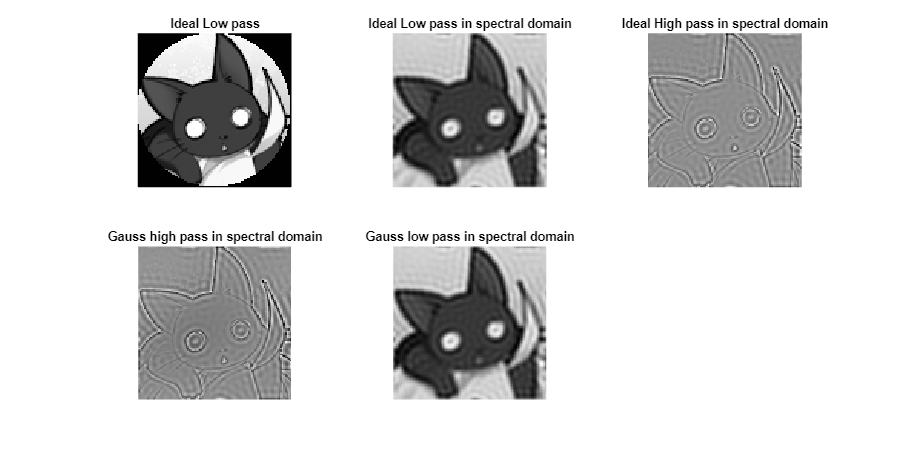

title("Gauss low pass in spectral domain");

close all;

foo = figure('Position', [100, 100, 2024, 1000]);

subplot(1,2,1);
imshow(ifft2(ifftshift(perfect_low_pass(shifty_cat, 20))), []);

title("Ideal Low pass in spectral domain");

subplot(1,2,2);
imshow(ifft2(ifftshift(gauss_low_pass(shifty_cat, 20))), []);

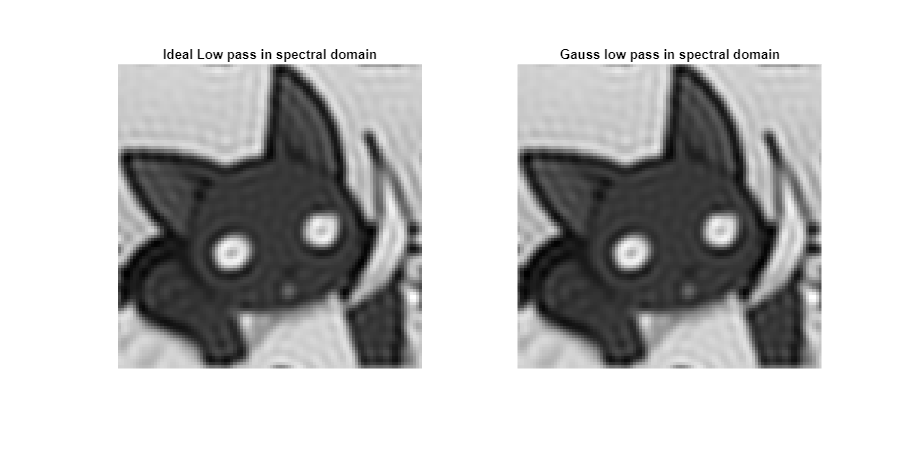

title("Gauss low pass in spectral domain");

For our low pass filters, they slightly differ, the gauss filter seems to be less "noisy", I'm assuming this is because of the gradual filtration rather than boolean 0 or 1 values for ideal low pass. 

close all;

foo = figure('Position', [100, 100, 2024, 1000]);

subplot(1,2,1);
imshow(ifft2(ifftshift(gauss_high_pass(shifty_cat, 40))), []);

title("Gauss high pass in spectral domain");

subplot(1,2,2);
imshow(ifft2(ifftshift(perfect_high_pass(shifty_cat, 40))), []);

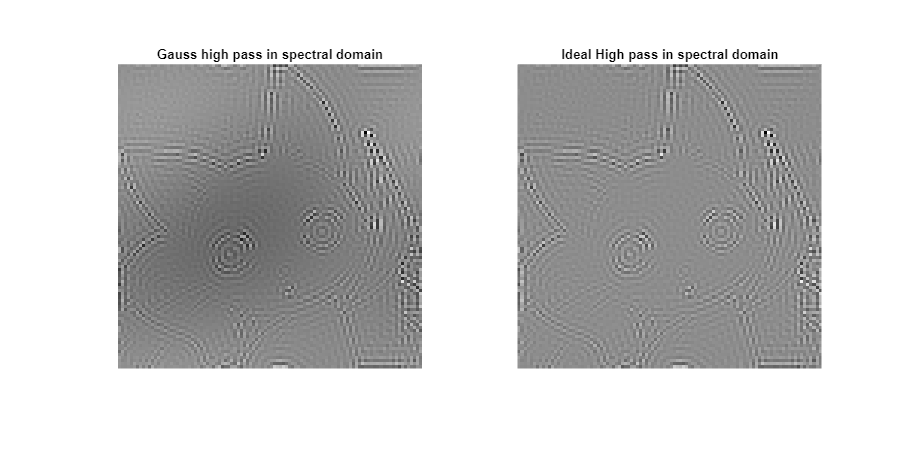

title("Ideal High pass in spectral domain");

Both high pass filters seem to be doing a good job at highlighting the edges, specifficaly of the cat in the image. With gauss high pass filter we can see a sort of gradiant in the backroung, whilest in ideal high pass filter there isn't one. Filters differ slightly but on this speciffic example, they both do the edge highliting job about equaly well.

### **Functions**

function ret = perfect_low_pass(img, r)
    width = length(img);
    height = length(img(:,1));
    toRet = zeros(width, height);
    for x = 1:width
        for y = 1:height
            if (x - round(width/2))^2 + (y - round(height/2))^2 < r^2
                toRet(x,y) = img(x, y);
            else
                toRet(x, y) = 1;
            end
        end
    end
    ret = toRet;
end

function ret = gauss_low_pass(img, r)
    width = length(img);
    height = length(img(:,1));
    toRet = zeros(width, height);
    leGauss = fspecial("gaussian", [100, 100]);
    for x = 1:width
        for y = 1:height
            if (x - round(width/2))^2 + (y - round(height/2))^2 < r^2
                toRet(x,y) = img(x, y);
            else
                toRet(x, y) = img(x,y) * leGauss(x,y);
            end
        end
    end
    ret = toRet;
end

function ret = gauss_high_pass(img, r)
    width = length(img);
    height = length(img(:,1));
    toRet = zeros(width, height);
    leGauss = fspecial("gaussian", [100, 100]);
    for x = 1:width
        for y = 1:height
            if (x - round(width/2))^2 + (y - round(height/2))^2 > r^2
                toRet(x,y) = img(x, y);
            else
                toRet(x, y) = img(x,y) * leGauss(x,y);
            end
        end
    end
    ret = toRet;
end

function ret = perfect_high_pass(img, r)
    width = length(img);
    height = length(img(:,1));
    toRet = zeros(width, height);
    for x = 1:width
        for y = 1:height
            if (x - round(width/2))^2 + (y - round(height/2))^2 > r^2
                toRet(x,y) = img(x, y);
            else
                toRet(x, y) = 1;
            end
        end
    end
    ret = toRet;
end